# Standard Operating Policy

## Define model params

addpath('utils\');
param.nat.S = 211500000;
param.nat.beta = 86.6021881286577;
param.nat.alpha = 1.95062290363465;
param.nat.h0 = -1.27;

param.reg.w = 100;
param.reg.hmin = 0;
param.reg.hmax = 1.5;

param.reg.h1 = 0.3;
param.reg.h2 = 1.0;

param.reg.m1 = 300;
param.reg.m2 = 1000;

h_test = -2:0.01:2;
r_test = zeros(size(h_test));
idx = find(h_test>param.nat.h0);
r_test(idx) = param.nat.beta*(h_test(idx) - param.nat.h0).^param.nat.alpha;

### Regulated release function

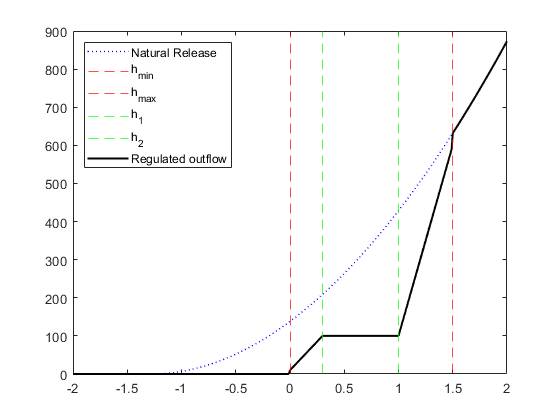

r_reg = getRegulatedRelease(h_test, param);

figure;
plot(h_test, r_test, ':b','LineWidth',1)
hold on;
xline(param.reg.hmin,'--r');
xline(param.reg.hmax,'--r');

xline(param.reg.h1,'--g');
xline(param.reg.h2,'--g');

plot(h_test, r_reg,'k','LineWidth',1.5)

legend('Natural Release', 'h_{min}', 'h_{max}', 'h_1', 'h_2','Regulated outflow','Location','northwest')

### Trajectories on real dynamics

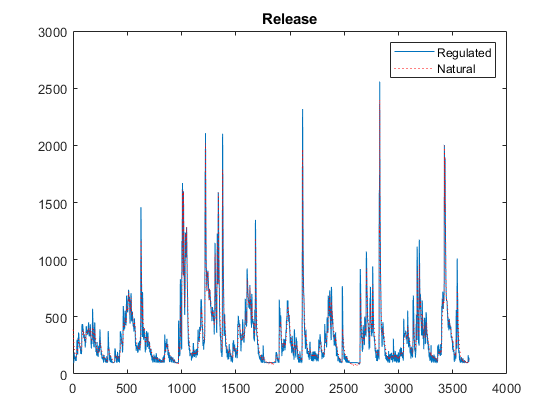

data = load("data\Verbano_inflows_74_83_nb.txt");
h_init = 0.88;
h_bar = 1.73;

[r_reg, s_reg, h_reg] = simRegLake(h_init, data, param);
[r_nat, s_nat, h_nat] = simNatLake(h_init, data, param);


figure; plot(r_reg); 
hold on; plot (r_nat, ':r');
title('Release');legend('Regulated','Natural');

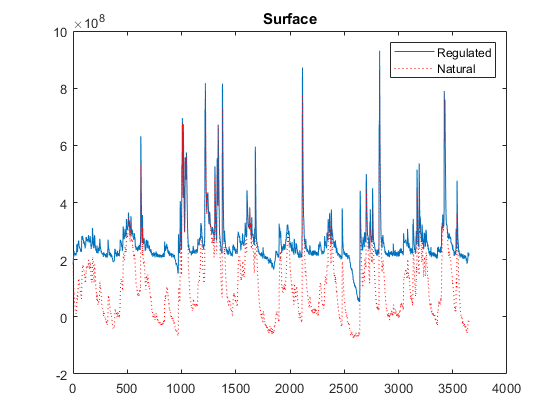


figure; plot(s_reg); 
hold on; plot (s_nat, ':r');
title('Surface');legend('Regulated','Natural');

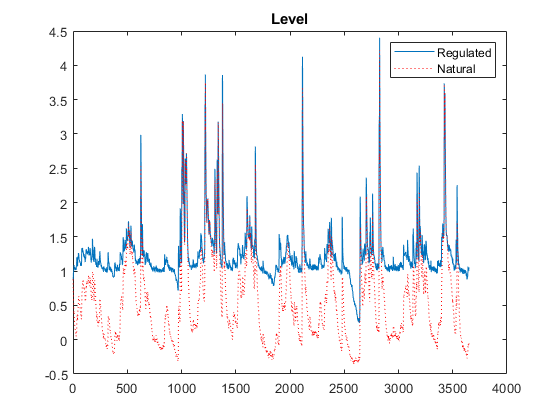


figure; plot(h_reg); 
hold on; plot (h_nat, ':r');
title('Level');legend('Regulated','Natural');


I_v2_reg = getVulnerability2(r_reg,param.reg.w,2)

I_v2_reg = 0.3590

I_v2_nat = getVulnerability2(r_nat,param.reg.w,2)

I_v2_nat = 10.1318


%     TODO: Params for lake Verbano
params2.p3 = 0.081;
params2.p2 = -0.483;
params2.p1 = 1.506;
params2.p0 = -1.578;
S = getFlooding2(h_reg, h_bar, params2);
I_f2_reg = mean(S)

I_f2_reg = 0.0286

S = getFlooding2(h_nat, h_bar, params2);
I_f2_nat = mean(S)

I_f2_nat = 0.0239

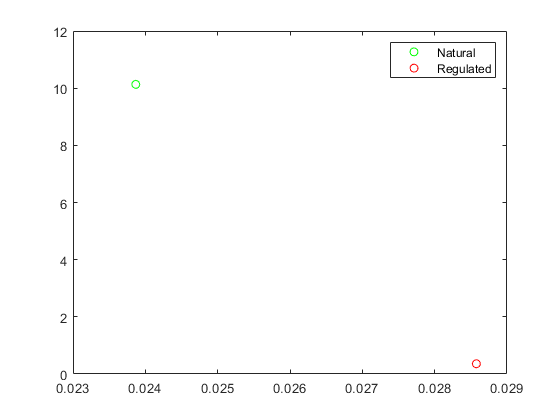


figure;
plot(I_f2_nat, I_v2_nat, 'og');
hold on;
plot(I_f2_reg, I_v2_reg, 'or');
legend('Natural', 'Regulated')

## NSGA-II 

Multiobjective policy optimization


global opt_inputs
opt_inputs.data = [nan; data];
opt_inputs.h_init = h_init;
opt_inputs.param = param;
opt_inputs.h_bar = h_bar;

addpath("NSGA2")
pop = 30; % Population
gen = 15; % Generations
M = 2; % Objective functions
V = 4; % Params

% Range space for variables h1 h2 m1 m2 respectivelly
min_range = [ 0.3 0.5 250 400 ] ; 
max_range = [ 0.5 1.5 350 2000 ] ;

[ chromosome_0, chromosome15 ] = nsga_2(pop,gen,M,V,min_range,max_range);


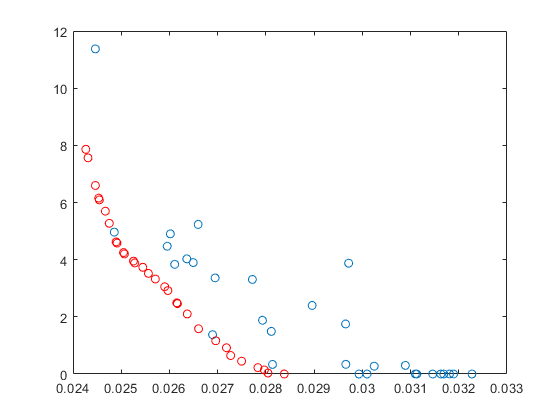

figure; plot( chromosome_0(:,end), chromosome_0(:,end-1), 'o') ; 
hold on; plot( chromosome15(:,6), chromosome15(:,5), 'ro')

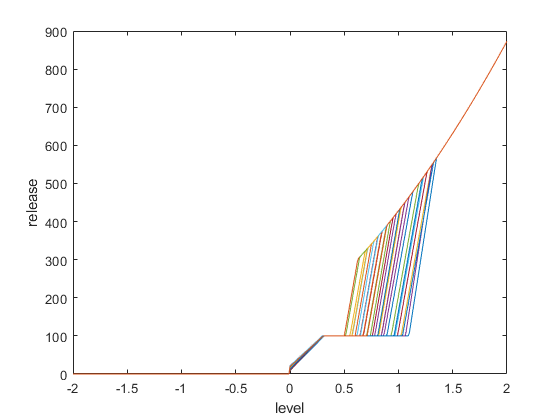

% decision space
for i = 1:pop
    xi = chromosome15(i,1:4);
    param.reg.h1 = xi(1);
    param.reg.h2 = xi(2);
    param.reg.m1 = xi(3);
    param.reg.m2 = xi(4);
    r_test(i,:) = getRegulatedRelease(h_test, param);
end

figure; plot( h_test, r_test );
xlabel('level'); ylabel('release');